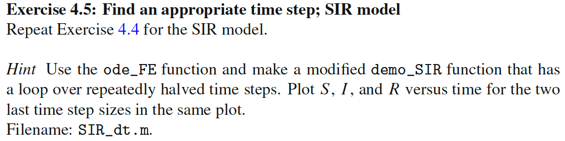

function SIR_dt()
    % Parameters
    beta = 0.3;   % Transmission rate
    gamma = 0.1;  % Recovery rate
    T = 160;      % Total time
    S0 = 999;     % Initial susceptible population
    I0 = 1;       % Initial infected population
    R0 = 0;       % Initial recovered population
    U_0 = [S0, I0, R0];  % Initial conditions vector

    % Function handle for the SIR model
    f = @(u, t) [-beta * u(1) * u(2); 
                  beta * u(1) * u(2) - gamma * u(2); 
                  gamma * u(2)];

    % Initial time step
    dt = 1.0;
    tol = 1e-3;  % Tolerance for convergence
    max_iter = 10;  % Maximum number of iterations

    % Storage for previous solution
    u_prev = [];
    t_prev = [];

    for iter = 1:max_iter
        % Solve ODE using Forward Euler method
        [u, t] = ode_FE(f, U_0, dt, T);

        % Plot results
        figure;
        plot(t, u(:,1), 'b', t, u(:,2), 'r', t, u(:,3), 'g');
        legend('Susceptible', 'Infected', 'Recovered');
        title(['SIR Model Solution with dt = ', num2str(dt)]);
        xlabel('Time');
        ylabel('Population');
        grid on;

        % Check for convergence
        if ~isempty(u_prev)
            % Interpolate previous solution to current time points
            u_prev_interp = interp1(t_prev, u_prev, t, 'linear');

            % Compute maximum difference
            max_diff = max(max(abs(u - u_prev_interp)));

            if max_diff < tol
                disp(['Convergence achieved with dt = ', num2str(dt)]);
                break;
            end
        end

        % Update previous solution
        u_prev = u;
        t_prev = t;

        % Halve the time step for the next iteration
        dt = dt / 2;
    end

    if iter == max_iter
        disp('Maximum iterations reached without convergence.');
    end
end


SIR_dt()

Unable to perform assignment because the size of the left side is 1-by-3 and the size of the right side is 3-by-3.

Error in ode_FE (line 8)
        u(n+1,:)  = u(n,:) + dt * f(u(n,:), t(n));

Error in SIR_dt>SIR_dt (line 27)
        [u, t] = ode_FE(f, U_0, dt, T);